load eigendata.mat;

[i1,i2,i3] = size(images)

i1 = 75

i2 = 256

i3 = 256

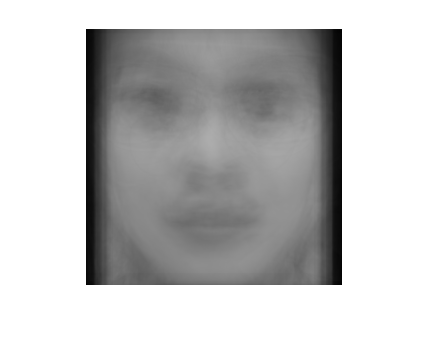

flat_sz = i2*i3;
sum = zeros(1,flat_sz);
for i = 1:i1
    img = images(i,:);
    sum = sum+img;
end
avg = sum / i1;
draw_face(avg,i2,i3);

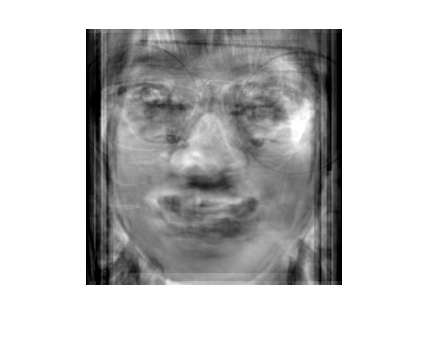

A = zeros(i1,flat_sz);
for i=1:i1
    img = images(i,:);
    diff = img - avg;
    A(i,:) = diff;
end

AAT = A * A';
[V,D] = eig(AAT);
ef = A' * V(:,50) + avg';
draw_face(ef,i2,i3)

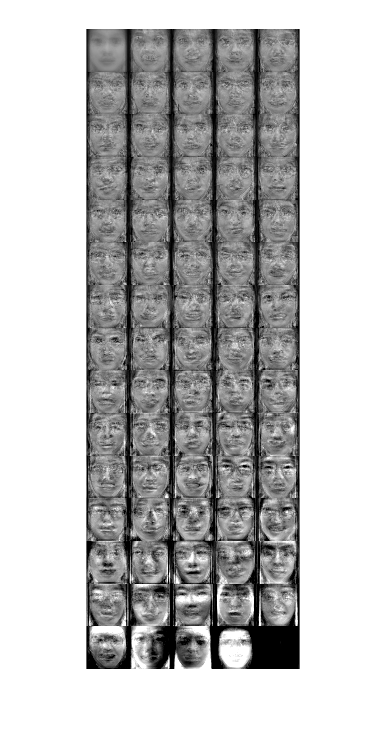

eigen_faces = eig_vec_to_imgs(V,A,avg,75,i2,i3);
eigen_face_grid = img_grid(eigen_faces,5);
imshow(eigen_face_grid);

imwrite(eigen_face_grid,'eigen_faces.png');

function rst = draw_face(vec,N1,N2)
    img = reshape(vec,N1,N2);
    imshow(uint8(img));
end

function imgs = eig_vec_to_imgs( V, A, avg, N, sz1, sz2 )
    imgs = zeros(N,sz1,sz2,'uint8');
    for i = 1:N
        vec = A' * V(:,i) + avg';
        imgs(i,:,:) = reshape(vec,sz1,sz2);
    end
end

function canvas = img_grid(imgs,N)
    [i,j,k] = size(imgs);
    M = ceil(i/N);
    canvas = zeros(M*j,N*k,'uint8');
    for idx = 1:i
       r = floor((idx-1)/N);
       c = mod((idx-1),N);
       offset_r = j*r;
       offset_c = k*c;
       canvas(offset_r+1:offset_r+j,offset_c+1:offset_c+k) = squeeze(imgs(idx,:,:));
    end
end